## Atividade 02 - Série trigonométrica de Fourier

João Victor Pessoa de Lima dos Anjos; 23.01078-9

clear; 
close all;
clc;

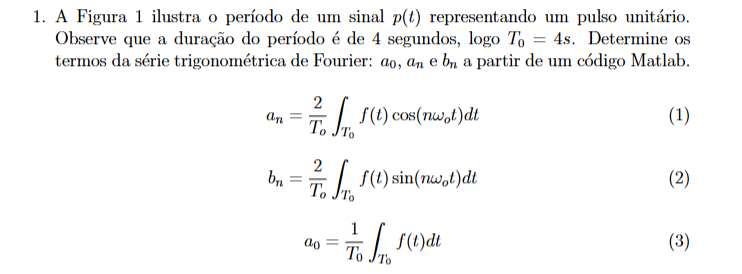

% Parâmetros básicos do sinal periódico
periodo = 4; %periodo
omega = 2 * pi / periodo;   
harmonicas = 20;               
tempo = linspace(0, 3*periodo, 1000); % Intervalo de tempo (0 a 12 segundos)

% Definindo a função periódica s(t)
sinal = @(t) double((mod(t, periodo) >= 0 & mod(t, periodo) < 0.5) | ...
                    (mod(t, periodo) >= 3.5 & mod(t, periodo) < periodo));

% Armazenando os coeficientes da série de Fourier
coef_a = zeros(1, harmonicas);
coef_b = zeros(1, harmonicas);

% Cálculo do coeficiente médio 
a0 = (1/periodo) * integral(@(t) sinal(t), 0, periodo, 'Waypoints', [0, 0.5, 3.5, periodo]);

% For para cálculo dos coeficientes das harmônicas (an e bn)
for k = 1:harmonicas
    termo_cos = @(t) sinal(t) .* cos(k * omega * t);
    termo_sin = @(t) sinal(t) .* sin(k * omega * t);
    coef_a(k) = (2/periodo) * integral(termo_cos, 0, periodo, 'Waypoints', [0, 0.5, 3.5, periodo]);
    coef_b(k) = (2/periodo) * integral(termo_sin, 0, periodo, 'Waypoints', [0, 0.5, 3.5, periodo]);
end

% Exibição dos coeficientes encontrados
fprintf('Coeficientes da função s(t):\n');

Coeficientes da função s(t):


fprintf('a0 = %.4f\n', a0);

a0 = 0.2500


fprintf('Coeficientes an:\n');

Coeficientes an:


disp(coef_a);

    0.4502    0.3183    0.1501   -0.0000   -0.0900   -0.1061   -0.0643    0.0000    0.0500    0.0637    0.0409   -0.0000   -0.0346   -0.0455   -0.0300   -0.0000    0.0265    0.0354    0.0237   -0.0000



fprintf('Coeficientes bn:\n');

Coeficientes bn:


disp(coef_b);

   1.0e-15 *

   -0.0796   -0.0906    0.0356    0.0763    0.1370    0.1769    0.1613    0.0798   -0.0226   -0.0347   -0.3105   -0.5343   -0.1353   -0.1908   -0.0770   -0.0297    0.0219   -0.1466   -0.0056    0.1334



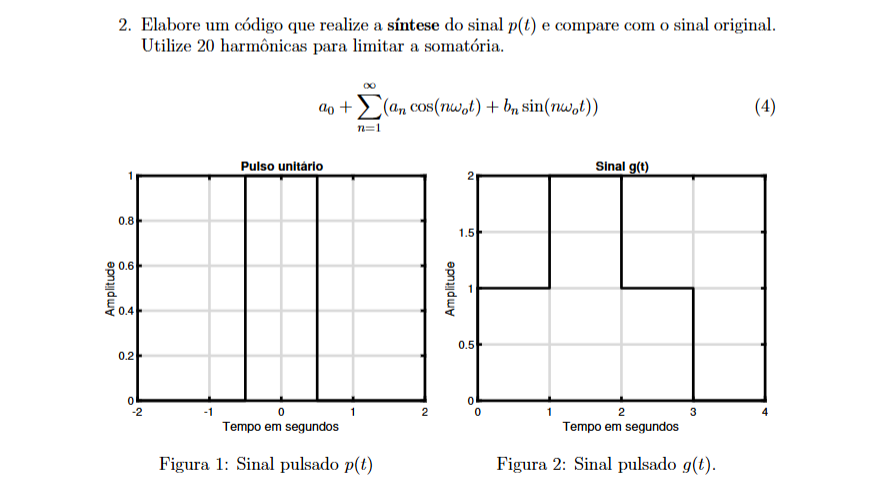

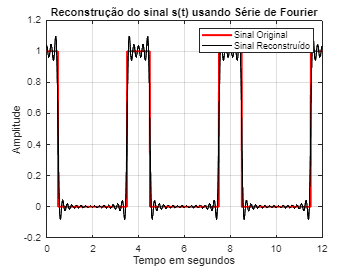

%Reconstrução do sinal
sinalReconstruido = a0 * ones(size(tempo));

% Acumula as contribuições das harmônicas para reconstruir o sinal
for k = 1:harmonicas
    sinalReconstruido = sinalReconstruido + coef_a(k) * cos(k * omega * tempo) + coef_b(k) * sin(k * omega * tempo);
end

% Plot para comparar o sinal original e o sinal reconstruído
figure;
plot(tempo, sinal(tempo), 'r-', 'LineWidth', 2); hold on;
plot(tempo, sinalReconstruido, 'k-', 'LineWidth', 1); hold off;
xlabel('Tempo em segundos');
ylabel('Amplitude');
title('Reconstrução do sinal s(t) usando Série de Fourier');
legend('Sinal Original', 'Sinal Reconstruído');
grid on;

% Definindo a função periódica h(t) com diferentes níveis em cada intervalo
h = @(t) (mod(t, periodo) >= 0   & mod(t, periodo) < 1) * 1 + ...
         (mod(t, periodo) >= 1   & mod(t, periodo) < 2) * 2 + ...
         (mod(t, periodo) >= 2   & mod(t, periodo) < 3) * 1 + ...
         (mod(t, periodo) >= 3   & mod(t, periodo) < 4) * 0;

% Armazenando os coeficientes de Fourier de h(t)
media_h = 0;
coef_h_a = zeros(1, harmonicas);
coef_h_b = zeros(1, harmonicas);

% Cálculo da média do sinal
media_h = (1/periodo) * integral(@(t) h(t), 0, periodo, 'Waypoints', [0, 1, 2, 3, 4]);

% Cálculo de an; bn
for m = 1:harmonicas
    termo_cos_h = @(t) h(t) .* cos(m * omega * t);
    termo_sin_h = @(t) h(t) .* sin(m * omega * t);
    coef_h_a(m) = (2/periodo) * integral(termo_cos_h, 0, periodo, 'Waypoints', [0, 1, 2, 3, 4]);
    coef_h_b(m) = (2/periodo) * integral(termo_sin_h, 0, periodo, 'Waypoints', [0, 1, 2, 3, 4]);
end

% Coeficientes da função h(t)
fprintf('Coeficientes da função h(t):\n');

Coeficientes da função h(t):


fprintf('a0 = %.2f\n', media_h);

a0 = 1.00


fprintf('Coeficientes an:\n');

Coeficientes an:


disp(coef_h_a);

   -0.6366   -0.0000    0.2122    0.0000   -0.1273    0.0000    0.0909    0.0000   -0.0707    0.0000    0.0579    0.0000   -0.0490   -0.0000    0.0424    0.0000   -0.0374   -0.0000    0.0335    0.0000



fprintf('Coeficientes bn:\n');

Coeficientes bn:


disp(coef_h_b);

    0.6366    0.0000    0.2122    0.0000    0.1273    0.0000    0.0909   -0.0000    0.0707    0.0000    0.0579    0.0000    0.0490    0.0000    0.0424   -0.0000    0.0374    0.0000    0.0335   -0.0000



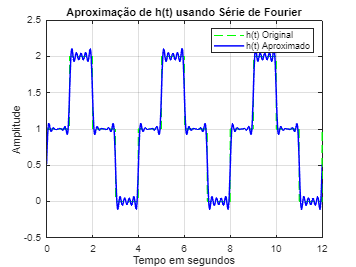

% Geração do sinal reconstruído a partir do termo constante da série
sinal_fourier = media_h * ones(size(tempo));

% harmônicas -> da série de Fourier
for idx = 1:harmonicas
    sinal_fourier = sinal_fourier + coef_h_a(idx) * cos(idx * omega * tempo) + ...
                                      coef_h_b(idx) * sin(idx * omega * tempo);
end

% Comparação de sinais (gráficos)
figure;
plot(tempo, h(tempo), 'g--', 'LineWidth', 1); hold on;
plot(tempo, sinal_fourier, 'b-', 'LineWidth', 1.5); hold off;

xlabel('Tempo em segundos');
ylabel('Amplitude');
title('Aproximação de h(t) usando Série de Fourier');
legend('h(t) Original', 'h(t) Aproximado');
grid on;

Há uma relação evidente entre as funções p(t) e g(t). No domínio do tempo, g(t) pode ser vista como uma soma de versões deslocadas e escaladas de p(t), ou seja, uma combinação linear de suas cópias deslocadas. Na análise de Fourier, os coeficientes de g(t) se assemelham aos de p(t), mas sofrem alterações de fase devido aos deslocamentos temporais. Esse efeito está diretamente ligado à propriedade de deslocamento da Transformada de Fourier.